%Enter Data
x = [0,1,2,3,4,5];
y = [0, 2.1, 4.1, 5.9, 7.9, 10.2];

%Model Equation
model = 'm*x';
IV = 'x';
DV = 'y';

%Create and perform the curve fit
newfit = fittype(model, 'Independent', IV, 'Dependent', DV);
[result, gof] = fit(x', y', newfit, 'StartPoint', 1)

result =      General model:
     result(x) = m*x
     Coefficients (with 95% confidence bounds):
       m =       2.011  (1.969, 2.053)

gof = struct with fields:
           sse: 0.0735
       rsquare: 0.9990
           dfe: 5
    adjrsquare: 0.9990
          rmse: 0.1212


 %Plot the fit and data points and create a plot objcect for formatting
 p = plot(result, x, y)

p =   2×1 Line array:

  Line    (data)
  Line    (fitted curve)



 %style the data points
 p(1).MarkerSize = 10;
 p(1).Marker = 'square';
 p(1).MarkerFaceColor = '#34b7eb';
 p(1).MarkerEdgeColor = '#eb3434';

 %Style the line of best fit
 p(2).LineWidth = 2;
 p(2).Color = '#131414'

p =   2×1 Line array:

  Line    (data)
  Line    (fitted curve)



 %Create graph object, set Latex formatting, and turn off legend
 graph = gca

graph =   Axes with properties:

             XLim: [0 5]
             YLim: [0 12]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


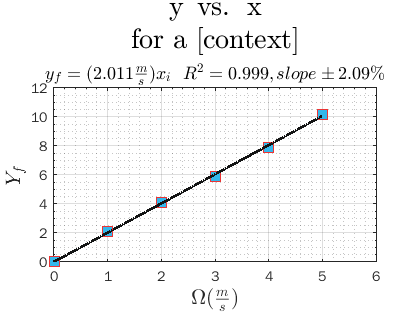

 set(graph, 'defaultTextInterpreter', 'latex');
 set(legend, 'visible', 'off');

 %Format title & Subtitle
 graph.Title.String = {'y\, vs.\, x', 'for a [context]'};
 graph.Title.FontSize = 20;
 %Subtitle, where we will place our equation and statistics (slope\pm =
 %slope plus or minus a value. To get value, take average of range from
 %result cfit (1.969 - 2.053)/2 and divide by slope (m) value.
 graph.Subtitle.String = '$y_{f} = (2.011\frac{m}{s})x_{i}$\,\,\,\,$R^2 = 0.999, slope\pm2.09\%$';
 graph.Subtitle.FontSize = 13;

 %Format x and y axes
 graph.XLabel.Interpreter = 'latex';
 graph.XLabel.String = '$\Omega (\frac{m}{s})$';
 graph.XLabel.FontSize = 15;
 graph.XLim = [0, 6];
 graph.XGrid = 'on';
 graph.XMinorGrid = 'on';
 graph.XMinorTick = 'on';

 graph.YLabel.Interpreter = 'latex';
 graph.YLabel.String = '$Y_{f}$';
 graph.YLabel.FontSize = 15;
 graph.YLim = [0, 12];
 graph.YGrid = 'on';
 graph.YMinorGrid = 'on';
 graph.YMinorTick = 'on';